## **Criteriul Modului - KESSLER**

#### Cu parte fixată:

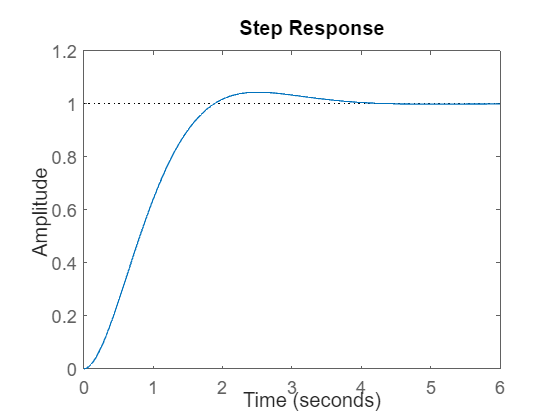

Hf = tf(0.1, conv([0.4 1], [6 1]));
Hr = tf([6 1], [0.08 0]);
Hcl = feedback(Hr * Hf, 1);
step(Hcl)

stepinfo(Hcl)

ans = struct with fields:
         RiseTime: 1.2156
    TransientTime: 3.3730
     SettlingTime: 3.3730
      SettlingMin: 0.9034
      SettlingMax: 1.0432
        Overshoot: 4.3210
       Undershoot: 0
             Peak: 1.0432
         PeakTime: 2.5052


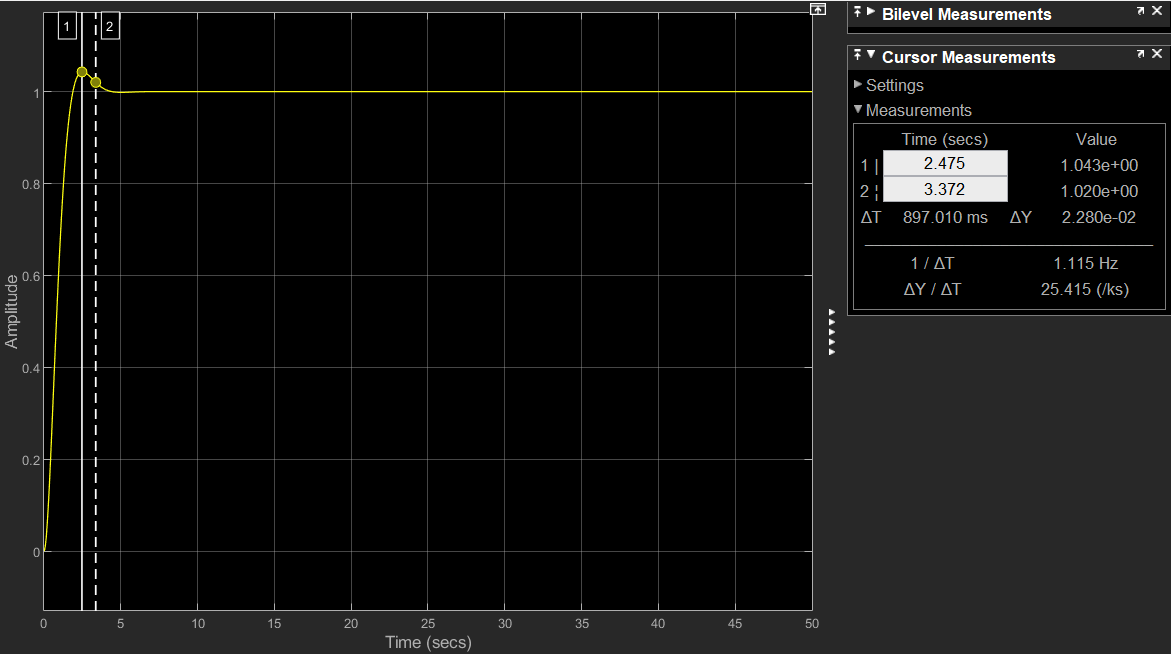

    a. Suprareglaj:

        Mp = (1.043 - 1) * 100 = 4.3%

    b. Timp de răspuns:

        tr = 3.37 s

        Te = 0.4; tr = 8.4 * 0.4 = 3.36 s

#### Cu separarea funcțiilor de transfer a componentelor sistemului:

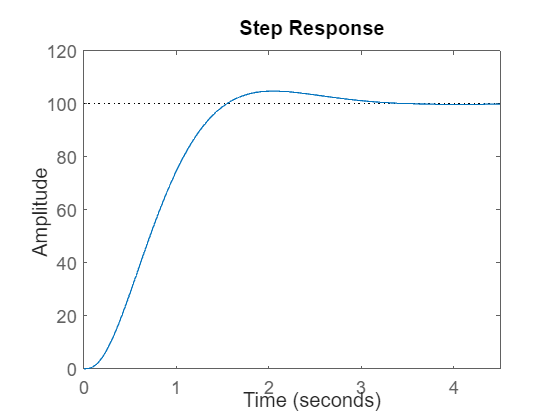

Hr = tf([6 1], [0.08 0]);
Hit = tf(2, conv([0.1 1], [6 1]));
Hee = tf(5, [0.2 1]);
Htm = tf(0.01, [0.1 1]);
Hcl = feedback(Hr * Hee * Hit, Htm);
step(Hcl)

stepinfo(Hcl)

ans = struct with fields:
         RiseTime: 0.9648
    TransientTime: 2.7798
     SettlingTime: 2.7798
      SettlingMin: 91.3681
      SettlingMax: 104.7509
        Overshoot: 4.7509
       Undershoot: 0
             Peak: 104.7509
         PeakTime: 2.0663


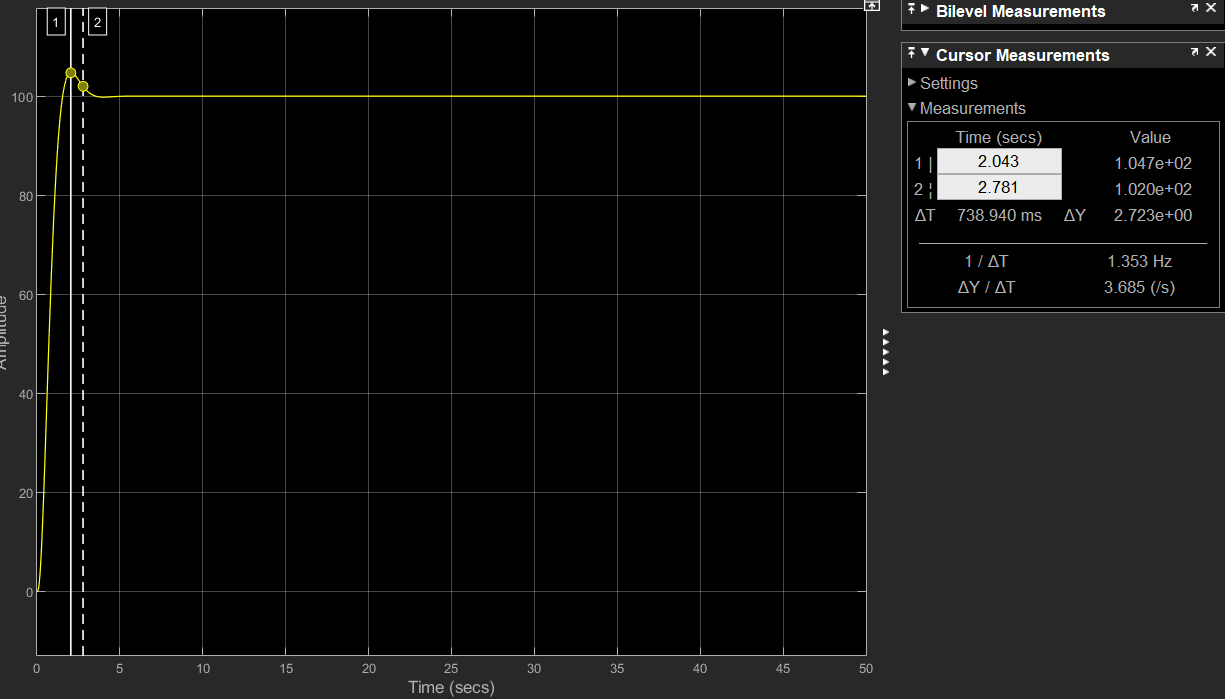

    a. Suprareglaj:

        Mp = (4.7 - 1) * 100 = 4.7%

    b. Timp de răspuns:

         tr = 2.78 s 

## Criteriul simetriei

#### Cu parte fixată

Hf = tf(0.1, conv([0.4 1], [6 1]));
Hr = tf([9.6 7.6 1], [0.128 0 0]);
minreal(Hr)

ans =
 
  75 s^2 + 59.38 s + 7.812
  ------------------------
            s^2
 
Continuous-time transfer function.
Model Properties


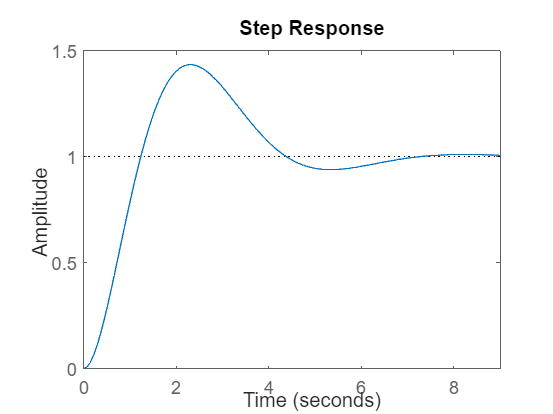

Hcl = feedback(Hf * Hr, 1);
step(Hcl)

stepinfo(Hcl)

ans = struct with fields:
         RiseTime: 0.8471
    TransientTime: 6.6204
     SettlingTime: 6.6204
      SettlingMin: 0.9390
      SettlingMax: 1.4339
        Overshoot: 43.3919
       Undershoot: 0
             Peak: 1.4339
         PeakTime: 2.2842


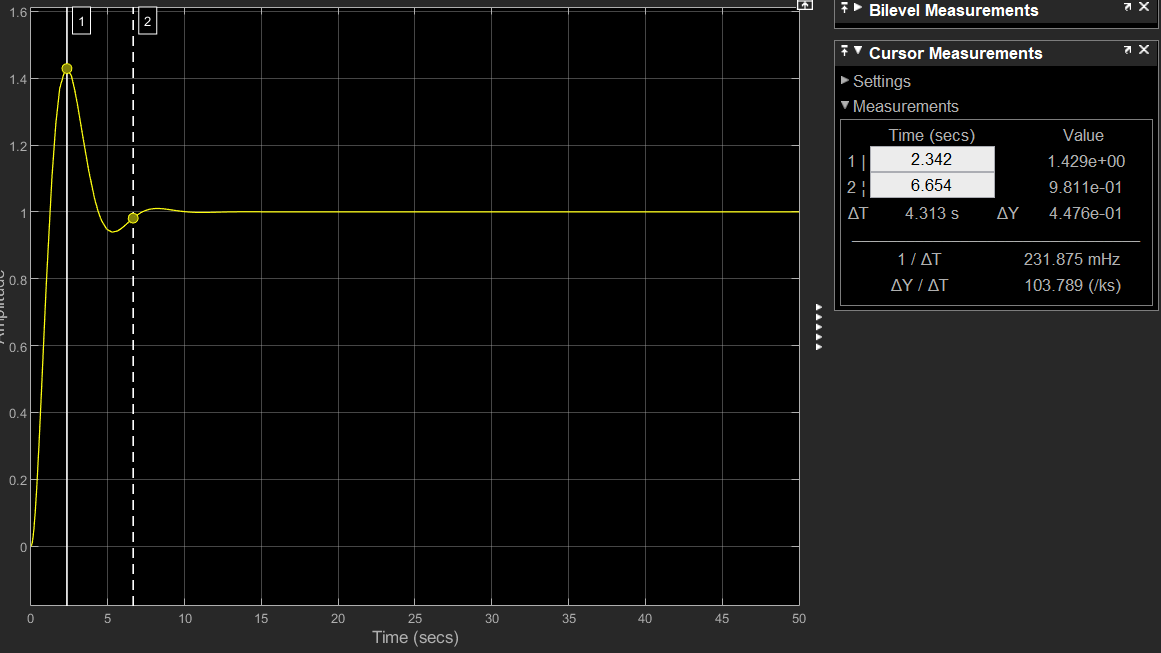

    a. Suprareglaj:

        Mp = (1.43 - 1) * 100 = 43%

    b. Timp de răspuns:

        tr = 6.6s

        Te = 0.4; tr = 16.5 * Te = 6.6s

#### Cu separarea funcțiilor de transfer a componentelor sistemului:

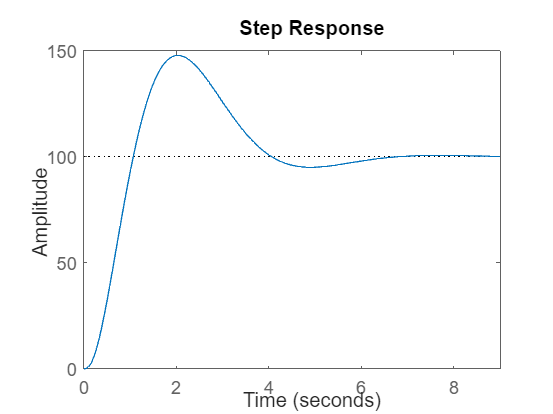

Hr = tf([9.6 7.6 1], [0.128 0 0]);
Hit = tf(2, conv([0.1 1], [6 1]));
Hee = tf(5, [0.2 1]);
Htm = tf(0.01, [0.1 1]);
Hcl = feedback(Hr * Hee * Hit, Htm);
step(Hcl)

stepinfo(Hcl)

ans = struct with fields:
         RiseTime: 0.6954
    TransientTime: 6.0146
     SettlingTime: 6.0146
      SettlingMin: 94.2912
      SettlingMax: 147.7456
        Overshoot: 47.7456
       Undershoot: 0
             Peak: 147.7456
         PeakTime: 2.0398


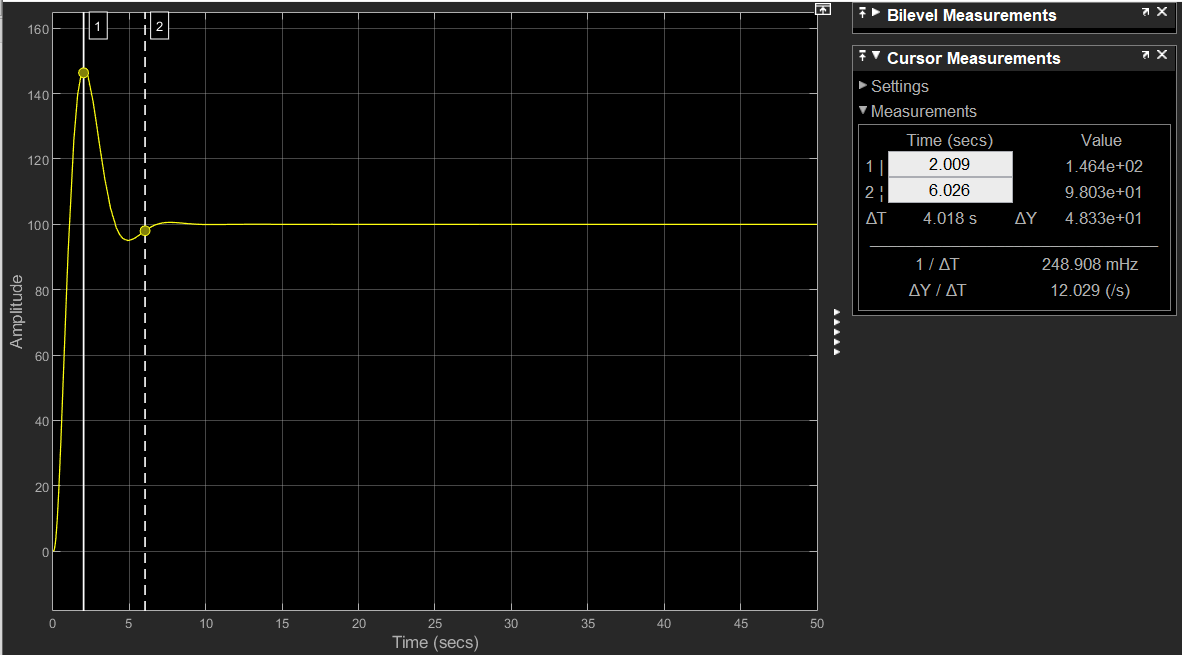

    a. Suprareglaj:

        Mp = (146 - 100) * 100 = 46%

    b. Timp de răspuns:

        tr = 6.02s